# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Práctica 3. Segmentación de Imágenes**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 07/11/2023**

El **objetivo** principal de esta práctica es familiarizarse con las técnicas de segmentación de imágenes:

- Desde niveles más sencillos que requieren intervención por parte del usuario (segmentación supervisada) para fijar umbrales, establecer los parámetros de los modelos etc., hasta niveles más complejos que trabajan de forma automática o semi-automática (segmentación no supervisada).

- A partir de técnicas basadas en el histograma, técnicas de agrupamiento (clustering) en regiones y técnicas de bordes. 

- Basadas en métodos lineales y no lineales de clasificación de cada píxel de la imagen en la región que le corresponda.

 A lo largo de la práctica se solicitará que: 

- Se aplique, de forma práctica algunas de las técnicas de segmentación estudiadas, verificando la problemática y limitaciones de las mismas.

- Se compare unas técnicas de segmentación con otras, analizando el porcentaje de acierto de las mismas.

- Se distinga la segmentación supervisada frente a la no supervisada.

- Se diferencie la segmentación basada en técnicas lineales frente a no lineales.

Se recomienda realizar pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), analizar los problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. Realice cada ejercicio como sección independiente, visualizando los resultados conjuntamente con subplot cuando sea conveniente, e insertando instrucciones para cerrar ventanas (*close all*), eliminar las variables del *workspace *(*clear all*) y pausar (*pause*), donde considere necesario. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

clear all;

**Ejercicios propuestos:**

** 1. Segmentación del histograma supervisada lineal:**

- Abra la imagen "pimientos.jpg".

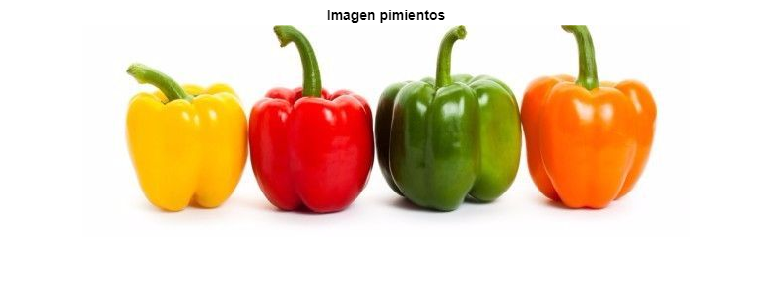

% Cargamos la imagen
I = imread('./imagenes/pimientos.jpg');
figure; imshow(I); title('Imagen pimientos');

imfinfo('./imagenes/pimientos.jpg').ColorType

ans = 'truecolor'

- Conviértala en imagen en niveles de gris.

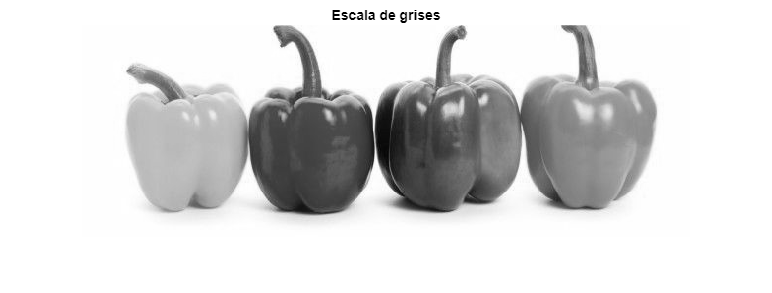

% Obtenemos la imagen en nivel de grises
I_gray = rgb2gray(I);
figure; imshow(I_gray); title('Escala de grises');

- Calcule y muestre el histograma de la imagen en niveles de gris.

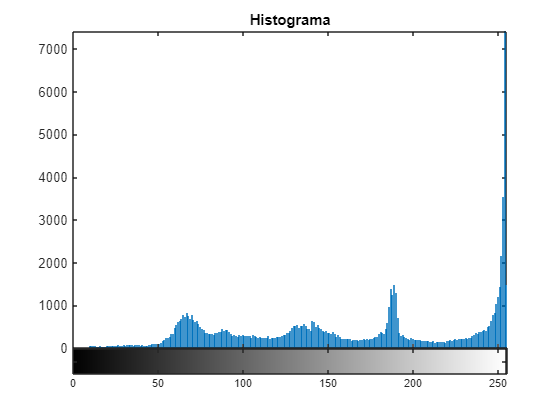

% Mostramos el histograma
figure; imhist(I_gray); title('Histograma')

- A la vista del histograma, utilice tantos umbrales como sea necesario y de los valores adecuados para segmentar cada uno de los objetos de la imagen. Puede introducirlos con un control deslizante (*numeric slider*) o pidiéndolos en el prompt de Matlab con la instrucción: umbral = input('Introduce valor del umbral X a la vista de la figura del histograma '). 

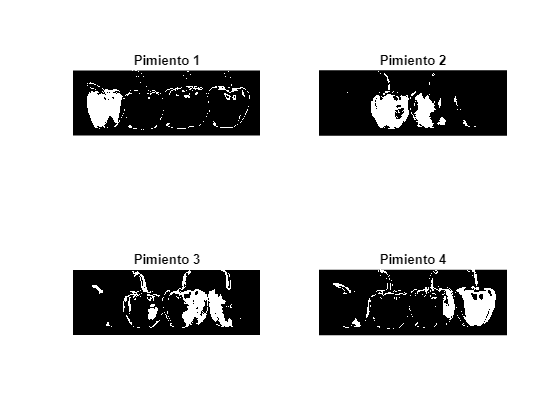

I_seg1 = (I_gray >= 179 & I_gray < 221);
I_seg2 = (I_gray >= 36 & I_gray < 86);
I_seg3 = (I_gray >= 81 & I_gray < 136);
I_seg4 = (I_gray >= 121 & I_gray < 173);

figure; 
subplot(2,2,1), imshow(I_seg1); title("Pimiento 1");
subplot(2,2,2), imshow(I_seg2); title("Pimiento 2");
subplot(2,2,3), imshow(I_seg3); title("Pimiento 3");
subplot(2,2,4), imshow(I_seg4); title("Pimiento 4");

- Visualice la segmentación (o con los objetos de distinto color en la misma imagen, o utilizando una imagen diferente para cada objeto).

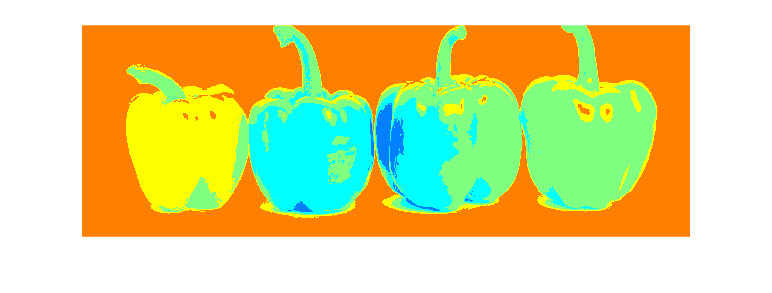

% Metemos los diferentes umbrales en la misma imagen
prueba = imquantize(I_gray, [36 85 175 221]);
prueba = label2rgb(prueba);

% Mostramos el resultado
figure, imshow(prueba);

- ¿Es fácil segmentar los distintos objetos? Justifique su respuesta.

**Comentario:**

- Al realizar la segmentación mediante el histograma de intensidad de la imagen, es complicado obtener únicamente los elementos deseados. En el resultado, se observa que hay elementos que deberían pertenecer a otra clase agrupados, lo cual es más evidente en el pimiento 2 y 3.

- Intente mejorar el resultado partiendo de la imagen en color y/o de sus distintas componentes.

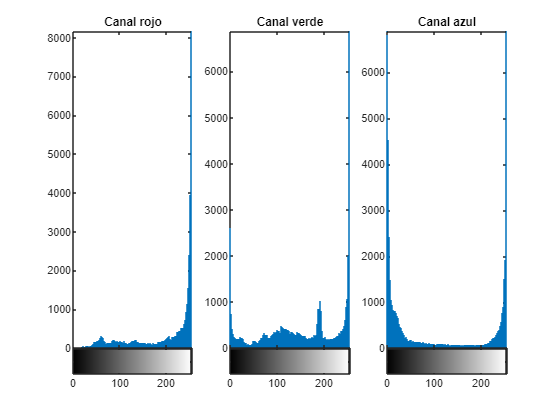

% Separamos los colores de la imagen
r_pimiento = I(:, :, 1);
g_pimiento = I(:, :, 2);
b_pimiento = I(:, :, 3);

figure;
subplot(1,3,1), imhist(r_pimiento); title('Canal rojo');
subplot(1,3,2), imhist(g_pimiento); title('Canal verde');
subplot(1,3,3), imhist(b_pimiento); title('Canal azul');

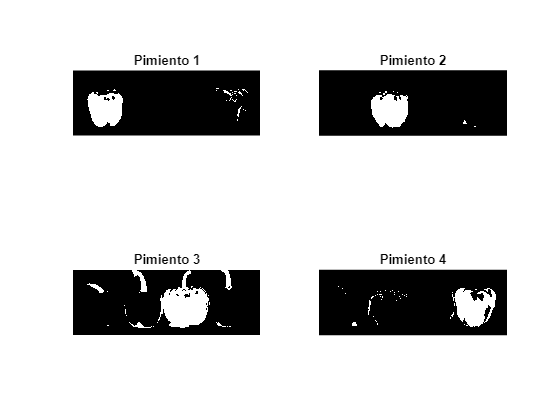

% Formamos el umbral para el pimiento 1
color_r = (r_pimiento >= 209 & r_pimiento <= 255);
color_g = (g_pimiento >= 135 & g_pimiento <= 255);
color_b = (b_pimiento >= 0 & b_pimiento <= 31);
pimiento1 = color_r & color_g & color_b;

% Formamos el umbral para el pimiento 2
color_r = (r_pimiento >= 156 & r_pimiento <= 255);
color_g = (g_pimiento >= 0 & g_pimiento <= 37);
color_b = (b_pimiento >= 0 & b_pimiento <= 94);
pimiento2 = color_r .* color_g .* color_b;

% Formamos el umbral para el pimiento 3
color_r = (r_pimiento >= 0 & r_pimiento <= 167);
color_g = (g_pimiento >= 0 & g_pimiento <= 205);
color_b = (b_pimiento >= 0 & b_pimiento <= 255);
pimiento3 = color_r .* color_g .* color_b;

% Formamos el umbral para el pimiento 4
color_r = (r_pimiento >= 136 & r_pimiento <= 255);
color_g = (g_pimiento >= 46 & g_pimiento <= 138);
color_b = (b_pimiento >= 0 & b_pimiento <= 51);
pimiento4 = color_r .* color_g .* color_b;


% mostramos los resultados 
figure, 
subplot(2,2,1), imshow(pimiento1); title('Pimiento 1');
subplot(2,2,2), imshow(pimiento2); title('Pimiento 2');
subplot(2,2,3), imshow(pimiento3); title('Pimiento 3');
subplot(2,2,4), imshow(pimiento4); title('Pimiento 4');

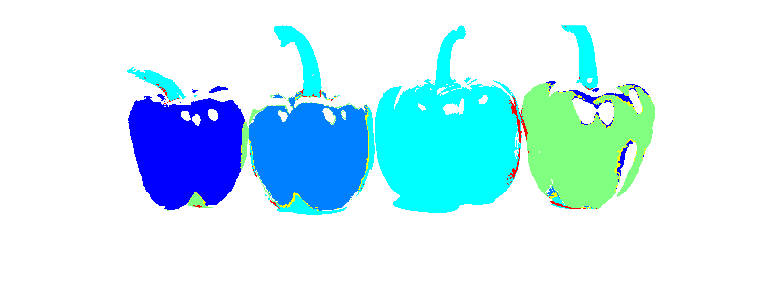

% Realizamos la segmentación
I_seg = pimiento1 + pimiento2 * 2 + pimiento3 * 3 + pimiento4 * 4;

rgb_pimiento = label2rgb(I_seg, 'jet');

figure, imshow(rgb_pimiento);

**Comentarios:**

- Al realizar la separación mediante la umbralización de los distintos canales de la imagen, hemos obtenido un resultado mejor que el anterior. Sin embargo, aún podemos observar que, en el caso del pimiento 3, de color verde, recoge parte de la imagen, en este caso, los tallos de todos los pimientos, debido a que también son de color verde.

**2. Segmentación no supervisada lineal:**

- **Umbralice **la imagen "eight.tif"** con la función *****imbinarize***, utilizando un umbral global calculado previamente con función ***graythresh*** de Matlab (método no supervisado: no requiere la observación del usuario del histograma, ni la elección de umbrales a partir del mismo): 

                    *   La función *graythresh *utiliza el método Otsu para escoger el umbral global de segmentación, minimizando la varianza dentro de los elementos de las clases y maximizándola entre clases.

                    *  La función *imbinarize *umbraliza imágenes en niveles de gris. Si la imagen original está en color es necesario transformarla previamente a niveles de gris, con la función correspondiente dependiendo de su formato (*rgb2gray*, etc...).  

                         level = graythresh(I);

                         BW = *imbinarize*(I,level);

                         figure, imshow(BW)

% Cargamos la imagen
I = imread('./imagenes/eight.tif');
imfinfo('./imagenes/eight.tif').ColorType     % grayscale

ans = 'grayscale'

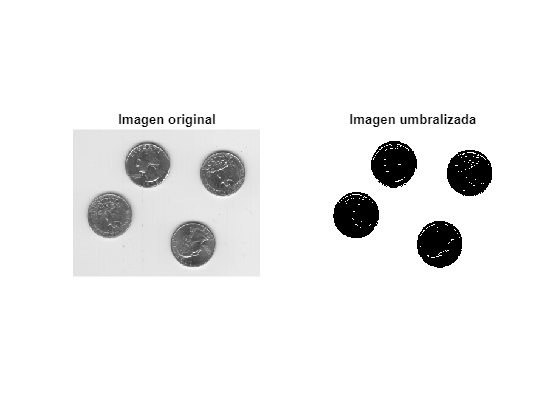

% Buscamos el umbral global
level = graythresh(I);

% Umbralizamos la imagen
BW = imbinarize(I, level);

% Mostramos el resultado
figure, 
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(BW); title('Imagen umbralizada');

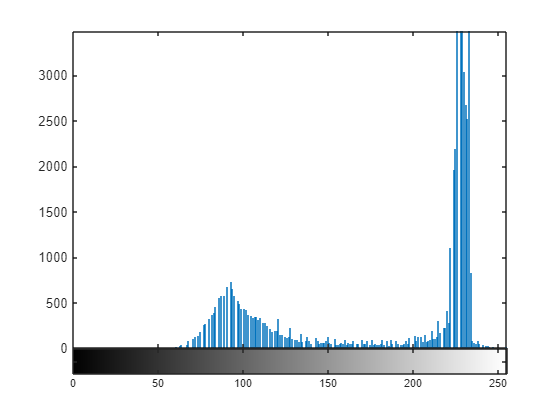

figure, imhist(I);

- ¿Funciona correctamente la segmentación no supervisada con la imagen "eigth.tif"? ¿Porqué?

**Comentario:**

- Del resultado, podemos observar que la segmentación no es perfecta. A pesar de haber detectado casi en su totalidad la moneda, podemos ver que dentro de ella hay partículas blancas. Para entender por qué, contamos con la imagen del histograma, que muestra que el fondo y las monedas no están separados completamente, sino que hay píxeles entre ellas que representan el brillo generado por las monedas, que luego al segmentar se aprecia como particulas blancas.

- Pruebe con otras imágenes de Matlab con histogramas de distintas formas ¿*graythresh* consigue segmentar adecuadamente las imágenes en todos los casos? En caso negativo ¿con qué tipo de imágenes suele funcionar mejor/peor?

% Imagen de granos de arroz
imfinfo('./imagenes/rice.png').ColorType

ans = 'grayscale'

% Imagen de monedas
imfinfo('./imagenes/coins.png').ColorType

ans = 'grayscale'

% Imagen de sangre
imfinfo('./imagenes/blood1.tif').ColorType

ans = 'grayscale'

% Imagen de fruta
imfinfo('./imagenes/pears.png').ColorType

ans = 'truecolor'

% Imagen de pimientos
imfinfo('./imagenes/pimientos.jpg').ColorType

ans = 'truecolor'

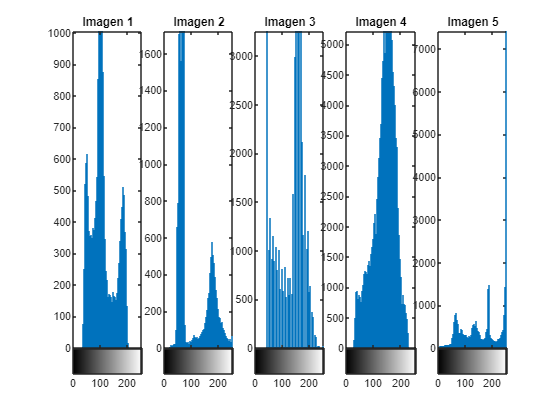

% Imagenes cargadas para realizar pruebas
I_collection = {imread('./imagenes/rice.png'), ...
                imread('./imagenes/coins.png'), ...
                imread('./imagenes/blood1.tif'), ...
                rgb2gray(imread('./imagenes/pears.png')), ...
                rgb2gray(imread('./imagenes/pimientos.jpg'))};

% Mostramos los histogramas
figure,
for i = 1:length(I_collection)
    subplot(1,5,i), imhist(I_collection{i}); title(sprintf('Imagen %d', i));
end

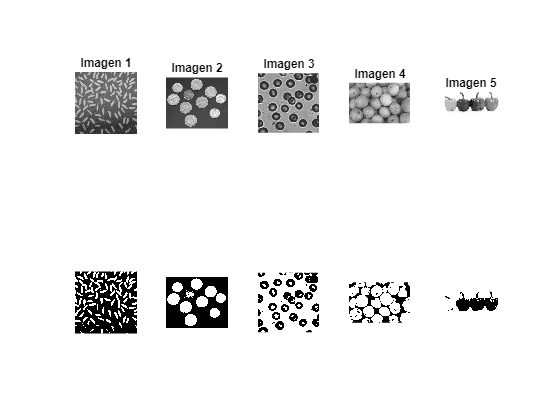

% Mostramos los resultados de la umbralizacion
figure,
for i = 1:length(I_collection)
    level = graythresh(I_collection{i});
    BW = imbinarize(I_collection{i}, level);

    subplot(2,5,i), imshow(I_collection{i}); title(sprintf('Imagen %d', i));
    subplot(2,5,i + 5), imshow(BW);
end

**Comentarios:**

- Después de evaluar la función `graythresh` para calcular el umbral de segmentación en diversas imágenes, hemos observado diferentes comportamientos. En el caso de la imagen 5, donde hay más de dos clases, la segmentación no se realiza de manera precisa. Además, en la imagen 2, debido a la falta de iluminación uniforme, una de las monedas no se obtiene de manera precisa, y también se observan partículas negras en otra de las monedas. Además, en la imagen 1, que presenta ruido, algunas de estas partículas se han considerado pertenecientes a la clase, lo que puede afectar negativamente la calidad de la segmentación.

**3. Compare los dos apartados anteriores: segmentación lineal supervisada frente a no supervisada, indicando ventajas e inconvenientes de cada una.**

**Comentarios:**

**Segmentación supervisada**

    Ventajas

- Ofrece un mayor control al seleccionar el umbral utilizado para la segmentación.

    Inconvenientes

- Seleccionar un umbral adecuado puede ser una tarea laboriosa y costosa en términos de tiempo.

- La calidad de los resultados puede depender de la elección del umbral.

**Segmentación No Supervisada**

    Ventajas

- No es necesario guiar el proceso para encontrar el umbral, ya que se realiza automáticamente.

    Inconvenientes

- Falta de control sobre el proceso de obtención del umbral.

- El umbral seleccionado puede tener dificultades para obtener el resultado esperado, como el ruido, y esto puede afectar la calidad de la segmentación.

**4. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

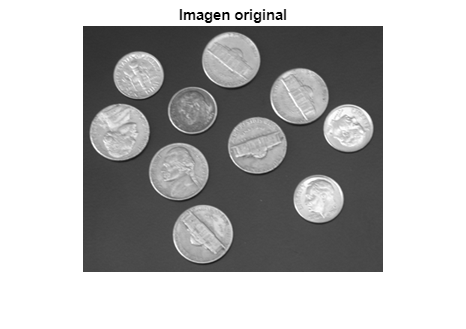

I = imread('./imagenes/coins.png');
figure, imshow(I); title('Imagen original');

- Detecte los bordes utilizando el filtro de Canny. Utilice controles deslizantes (*numeric sliders*) para configurar los distintos parámetros y visualice el efecto de las diferentes configuraciones. Comente los efectos sobre los bordes del cambio de cada parámetro.

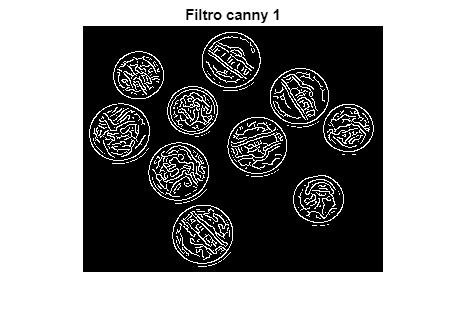

% Configuramos los parametros para el filtro Canny
threshold_low = 0;
threshold_high = 0.06;
sigma = 1;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 1');

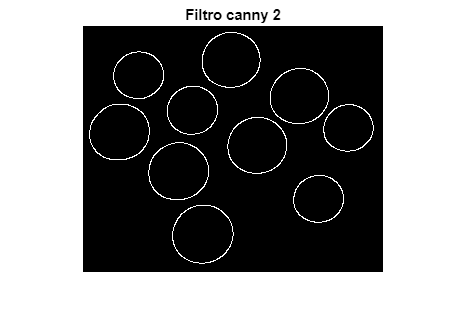

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');

- Cierre contornos dilatando los bordes obtenidos (*imdilate*). Visualice.

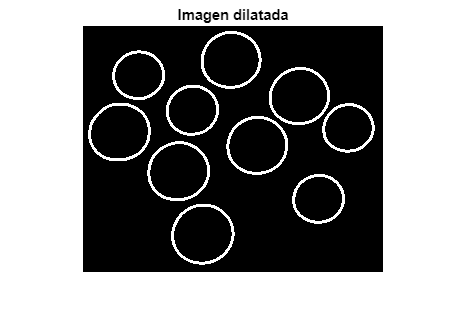

% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes 
BWdil = imdilate(BW, se);

figure, imshow(BWdil); title('Imagen dilatada');

- Rellene los contornos obtenidos.

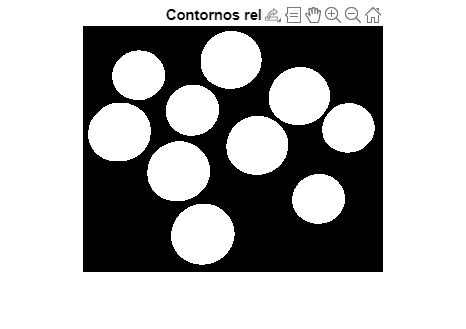

% Rellenamos los contornos
BWfill = imfill(BWdil, 'holes');

% Mostramos el resultado
figure, imshow(BWfill); title('Contornos rellenos');

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

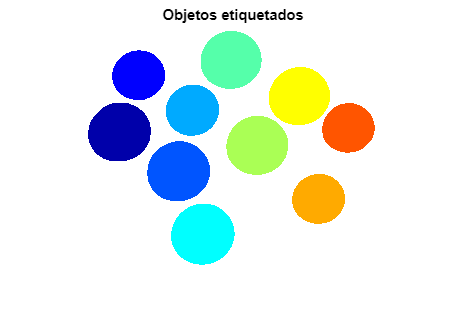

% Etiquetamos los objetos
L = bwlabel(BWfill);
%  Pintamos los objetos
L_RGB_CANNY = label2rgb(L);

% Mostramos el resultado
figure, imshow(L_RGB_CANNY); title('Objetos etiquetados');

**Comentarios:**

- Usando el filtro Canny, notamos que logramos detectar los bordes de manera precisa, incluso identificando los contornos del dibujo de la moneda

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel'``y` compare los resultados (canny - sobel). Justifique.

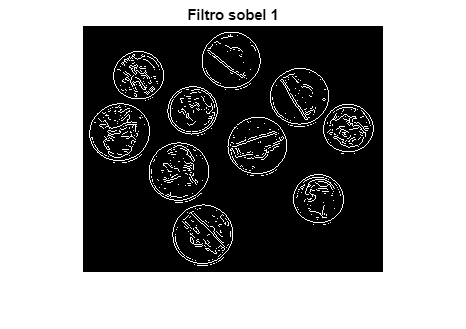

% Tomamos la imagen cargada anteriormente I
% Aplicamos el filtro sobel
BWs = edge(I, 'sobel', (graythresh(I) * .1));

% Mostamos el resultado
figure, imshow(BWs); title('Filtro sobel 1');

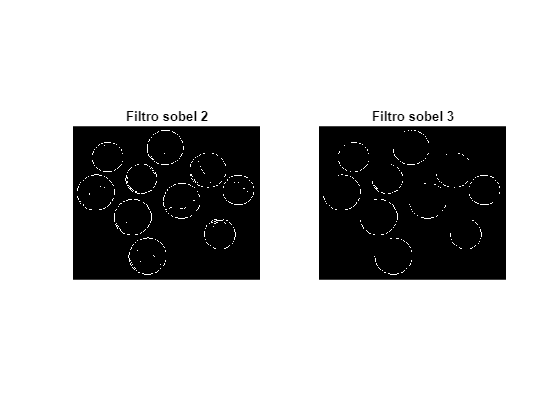

% Aplicamos el filtro sobel
BWs = edge(I, 'sobel', (graythresh(I) * .28));
BWs2 = edge(I, 'sobel', (graythresh(I) * .45));

% Mostamos el resultado
figure, 
subplot(1,2,1), imshow(BWs); title('Filtro sobel 2');
subplot(1,2,2), imshow(BWs2); title('Filtro sobel 3');

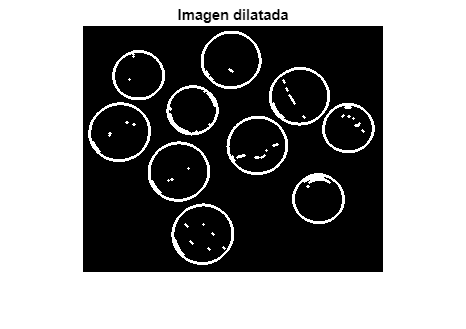

% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes
BWsdil = imdilate(BWs, se);

figure, imshow(BWsdil); title('Imagen dilatada');

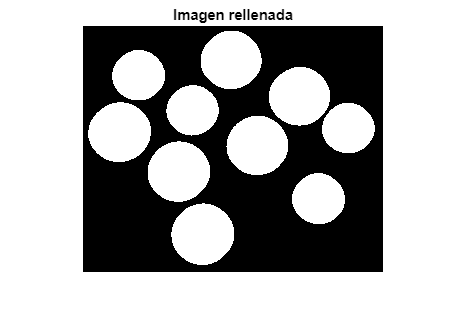

% Rellenamos los bordes
BWrellenada = bwfill(BWsdil,'holes');

figure, imshow(BWrellenada); title('Imagen rellenada');

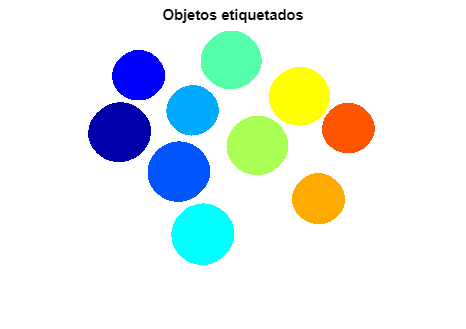

% Etiquetamos los objetos
L = bwlabel(BWrellenada);
% Pintamos los objetos
%numero_objetos = max(max(L));
L_RGB_SOBEL = label2rgb(L); 

figure, imshow(L_RGB_SOBEL); title('Objetos etiquetados');

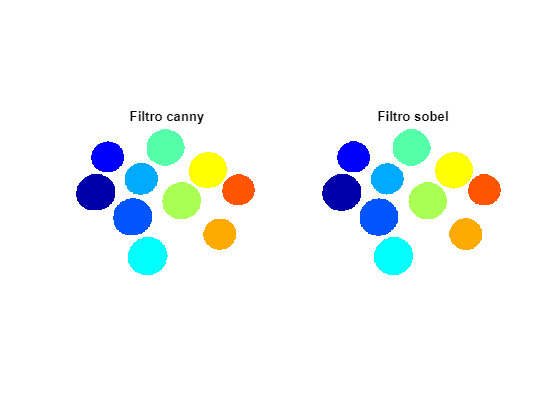

% Comparacion
figure, 
subplot(1,2,1), imshow(L_RGB_CANNY); title('Filtro canny');
subplot(1,2,2), imshow(L_RGB_SOBEL); title('Filtro sobel');

**Comentarios:**

- Podemos observar las diferencias principales al obtener el borde de las monedas. El operador Sobel es más sencillo de usar, ya que solo se modifica un parámetro. Sin embargo, el resultado no es tan sofisticado como lo es con el filtro Canny. No obstante, al realizar el relleno y etiquetado de los objetos, el resultado es el mismo.

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

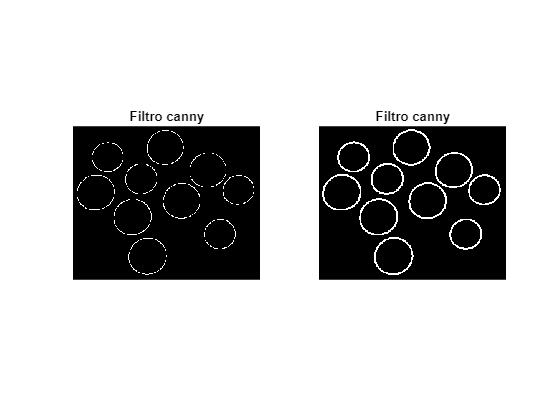

% Tomamos la imagen anteriormente cargada I
% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Seleccionamos el estructurante
se = [0 1 0; 1 1 1; 0 1 0];
% Dilatamos los bordes 
BWdil = imdilate(BW, se);

% Mostamos el resultado
figure, 
subplot(1,2,1), imshow(BW); title('Filtro canny');
subplot(1,2,2), imshow(BWdil); title('Filtro canny');

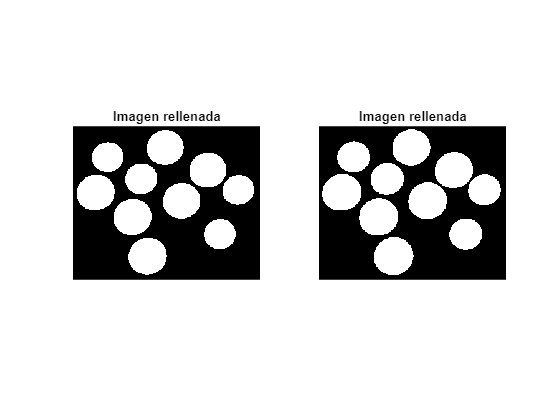

% Rellenamos los bordes
BWrellenada = bwfill(BW,'holes');
BWrellenadadil = bwfill(BWdil,'holes');

figure, 
subplot(1,2,1), imshow(BWrellenada); title('Imagen rellenada');
subplot(1,2,2), imshow(BWrellenadadil); title('Imagen rellenada');

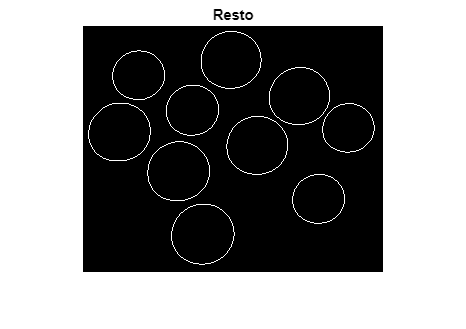

% Resto
figure, imshow(BWrellenadadil - BWrellenada); title('Resto');

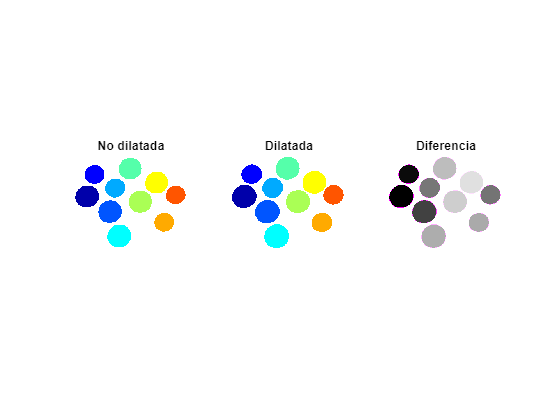

% Etiquetamos los objetos
L = bwlabel(BWrellenada);
% Pintamos los objetos
L_RGB_ND = label2rgb(L); 

% Etiquetamos los objetos
L = bwlabel(BWrellenadadil);
% Pintamos los objetos
L_RGB_D = label2rgb(L); 

figure, 
subplot(1,3,1), imshow(L_RGB_ND); title('No dilatada');
subplot(1,3,2), imshow(L_RGB_D); title('Dilatada');
subplot(1,3,3), imshow(imfuse(L_RGB_D, L_RGB_ND)); title('Diferencia');

**Comentarios:**

- Podemos observar que, al no realizar la dilatación, el objeto tiene un tamaño menor. Se puede notar en las diversas imágenes que la diferencia en este caso es de unos pocos píxeles en el contorno, y que el resultado final es muy similar. El resultado sería diferente si se utilizara un elemento estructurante más grande, como se verá en el apartado siguiente.

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');

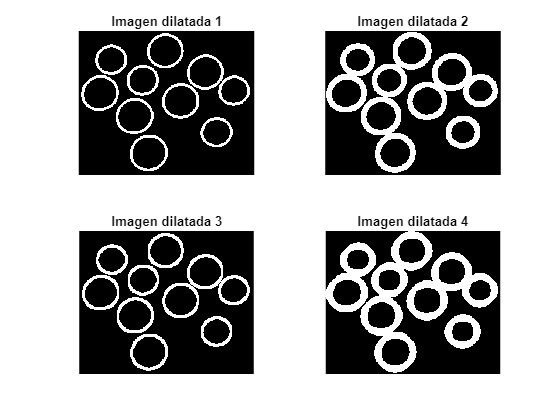

% Seleccionamos el estructurante
se = {strel('disk', 2), ...
    strel('disk', 5), ...
    strel("rectangle", [5 4]), ...
    strel("diamond", 6)};

BWdil = cell(1, 4);

figure,
for i = 1:4
    % Dilatamos los bordes 
    BWdil{i} = imdilate(BW, se{i});
    subplot(2,2,i), imshow(BWdil{i}); title(sprintf('Imagen dilatada %d',i));
end

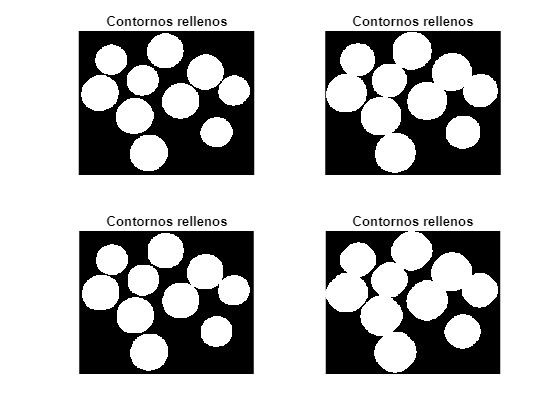

BWfill = cell(1, 4);
figure,
for i = 1:4
    % Rellenamos los contornos
    BWfill{i} = imfill(BWdil{i}, 'holes');

    % Mostramos el resultado
    subplot(2,2,i), imshow(BWfill{i}); title('Contornos rellenos');
end

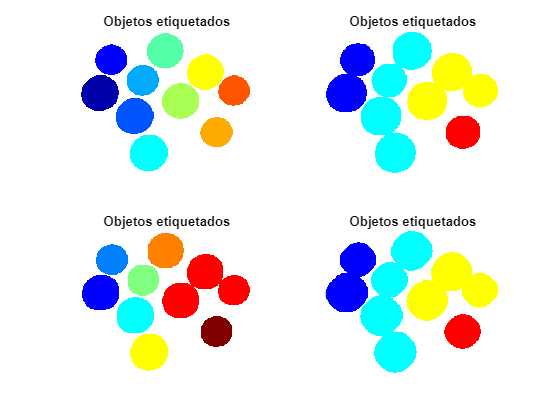

figure,
for i = 1:4
    % Etiquetamos los objetos
    L = bwlabel(BWfill{i});
    %  Pintamos los objetos
    L_RGB_CANNY = label2rgb(L);
    
    % Mostramos el resultado
    subplot(2,2,i), imshow(L_RGB_CANNY); title('Objetos etiquetados');
end

**Comentarios:**

- Al aplicar diferentes elementos estructurantes a la hora de realizar la dilatación, podemos observar que si el elemento estructurante es muy grande, los objetos tienden a fusionarse, y al realizar la segmentación, varios objetos se agrupan en uno solo. Por lo tanto, deducimos que la elección incorrecta del elemento estructurante conduce a un resultado no deseado.

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

% Configuramos los parametros para el filtro Canny
threshold_low = 0.21;
threshold_high = 0.47;
sigma = 2;
% Aplicamos el filtro canny con los parametros seleccionados
BW = edge(I, 'Canny', [threshold_low, threshold_high], sigma);

% Mostamos el resultado
figure, imshow(BW); title('Filtro canny 2');

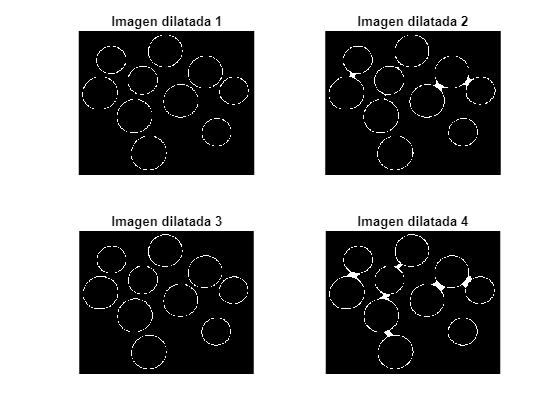

BWdil = cell(1, 4);

figure,
for i = 1:4
    % Dilatamos los bordes 
    BWdil{i} = imclose(BW, se{i});
    subplot(2,2,i), imshow(BWdil{i}); title(sprintf('Imagen dilatada %d',i));
end

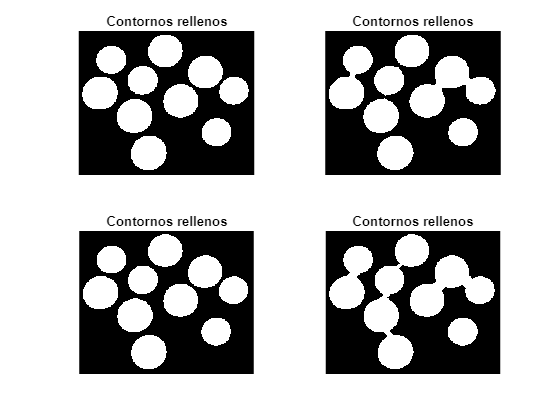

BWfill = cell(1, 4);
figure,
for i = 1:4
    % Rellenamos los contornos
    BWfill{i} = imfill(BWdil{i}, 'holes');

    % Mostramos el resultado
    subplot(2,2,i), imshow(BWfill{i}); title('Contornos rellenos');
end

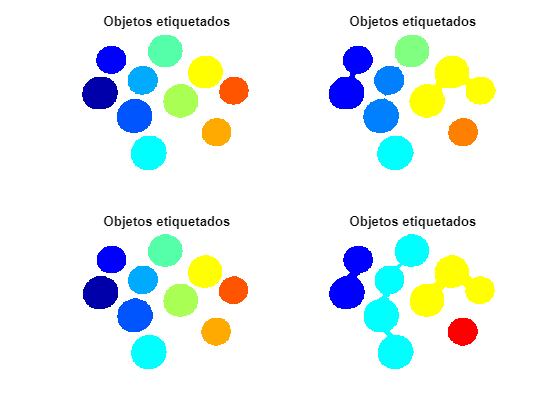

figure,
for i = 1:4
    % Etiquetamos los objetos
    L = bwlabel(BWfill{i});
    %  Pintamos los objetos
    L_RGB_CANNY = label2rgb(L);
    
    % Mostramos el resultado
    subplot(2,2,i), imshow(L_RGB_CANNY); title('Objetos etiquetados');
end

**Comentarios:**

- Al utilizar un cierre en lugar de una dilatación con los mismos elementos estructurantes que antes, observamos que en algunos casos aumenta el borde sin fusionarse con los de al lado, evitando la generación de objetos fusionados. Sin embargo, si el elemento estructurante es muy grande, al realizar el cierre queda un pequeño camino donde se fusionaron los elementos y no se pudo deshacer ese camino.

**5. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, pinte las 7 rectas más largas de la imagen **'despacho1.jpg'**. 

imfinfo('./imagenes/despacho1.jpg').ColorType

ans = 'truecolor'

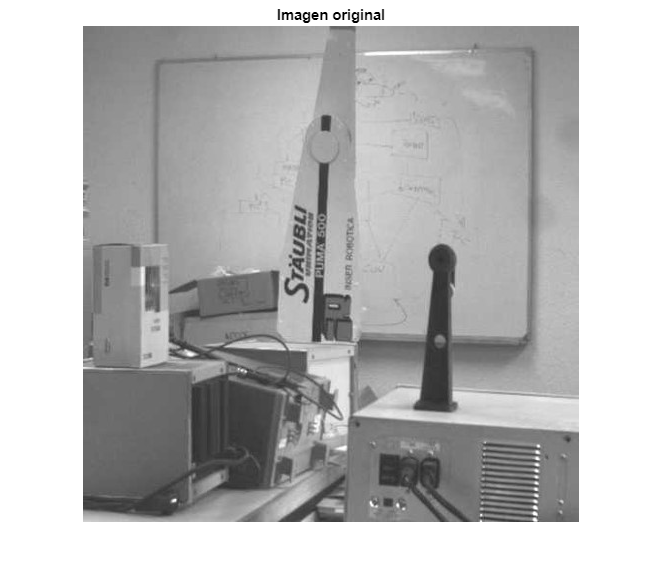

I = rgb2gray(imread('./imagenes/despacho1.jpg'));
figure, imshow(I); title('Imagen original');

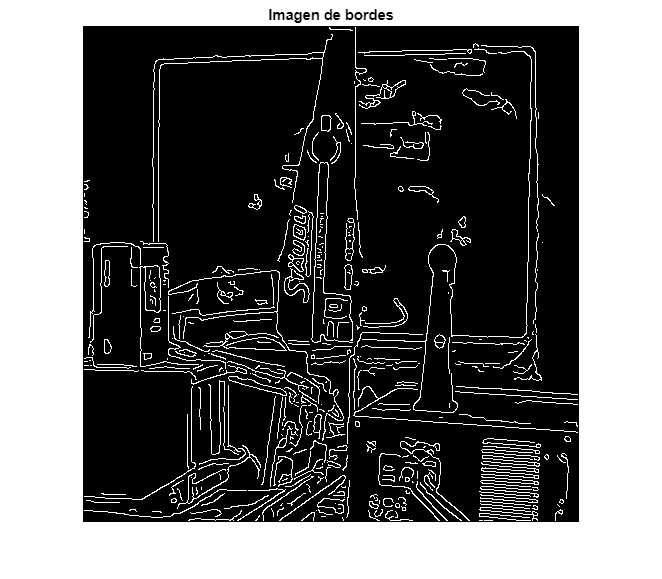

% Aplicamos un filtro canny sobre la imagen
BW = edge(I,'canny');
figure, imshow(BW); title('Imagen de bordes');

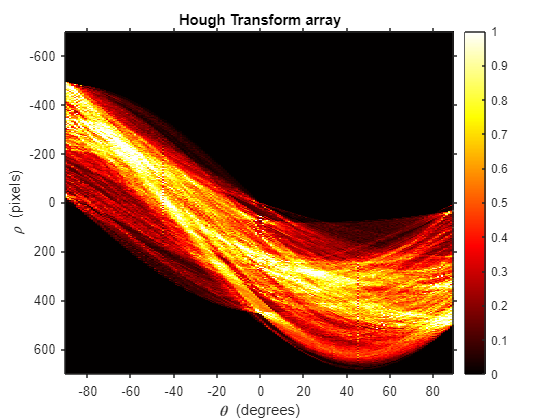

% Calculamos la transforamda de Hough
[H, theta, rho] = hough(BW);

figure,
imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
title('Hough Transform array'); xlabel('\theta (degrees)'); ylabel('\rho (pixels)'); 
axis on, axis normal; colormap(gca,hot); colorbar;

% Buscamos los picos en la transformada
th = ceil(0.65*max(H(:))); % umbral de búsqueda
max_peaks = 7; % 7 picos

% Coordenadas de los picos
P = houghpeaks(H, max_peaks, 'threshold', th)

P =          332           5
         742         179
        1150          92
         364           5
         772          91
         974          91
         942          93


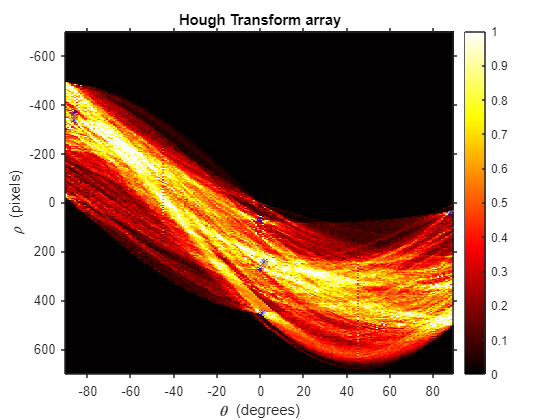

% Mostramos los picos en la imagen
x = theta(P(:,2)); 
y = rho(P(:,1)); 
hold on;
plot(x,y,'*','color','blue');
hold off;

% Obtenemos las 7 lineas largas
lines = houghlines(BW, theta, rho, P, 'FillGap', 90, 'MinLength', 30)

lines = 1×7 struct array with fields:
    point1
    point2
    theta
    rho


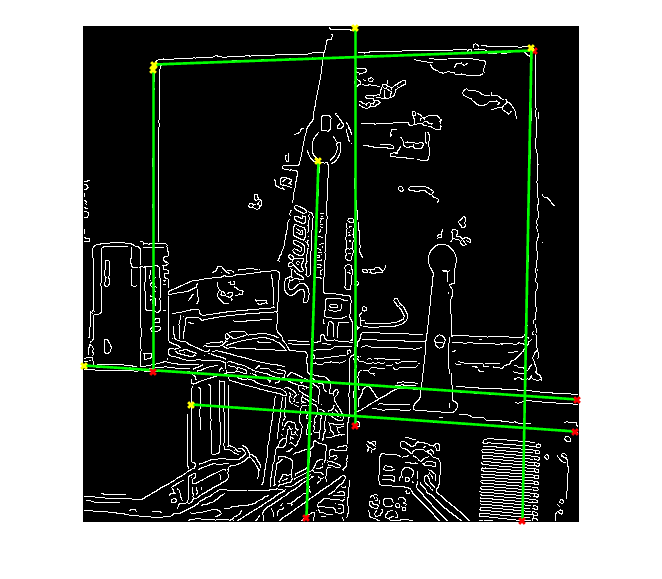

figure, 
imshow(BW), 
hold on 

for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre las líneas detectadas.

% Modificamos los parametros de la funcion
lines = houghlines(BW, theta, rho, P, 'FillGap', 10, 'MinLength', 4)

lines = 1×45 struct array with fields:
    point1
    point2
    theta
    rho


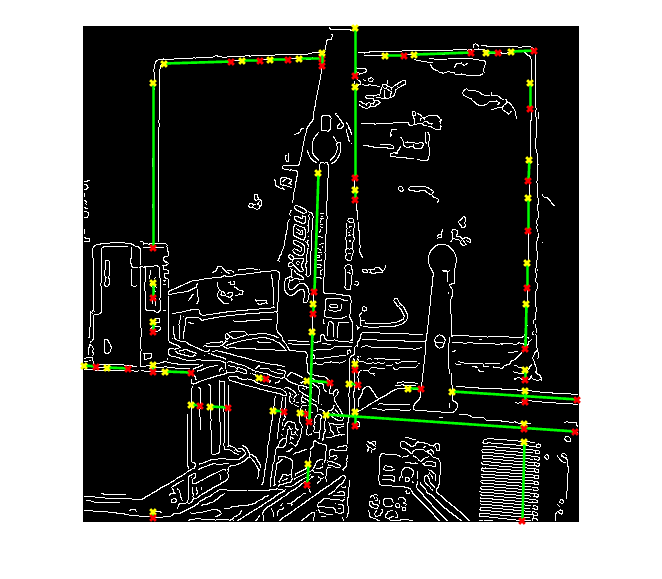

figure, 
imshow(BW), 
hold on 

for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end 

**Comentarios:**

- Al asignar valores distintos a las variables FillGap y MinLength, se observa un aumento en la segmentación de las líneas, adaptándose así a los trazos de la imagen original. Cuanto menor sea mas segmentos de menor tamaño se generan sobre la línea.

- Calcule el número de picos `length(P)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

% Numero de picos
length(P)

ans = 7

% Numero de lines
length(lines)

ans = 45

**Comentarios:**

- Los picos difieren de las líneas obtenidas debido a que una única línea en la imagen original puede corresponder a varios picos en la transformada de Hough. Como se puede observar en la imagen, todos estos picos representan segmentos que pertenecen a la misma línea principal en la imagen original.

**6. Detección de círculos utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y pinte el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

imfinfo('./imagenes/blood1.tif').ColorType

ans = 'grayscale'

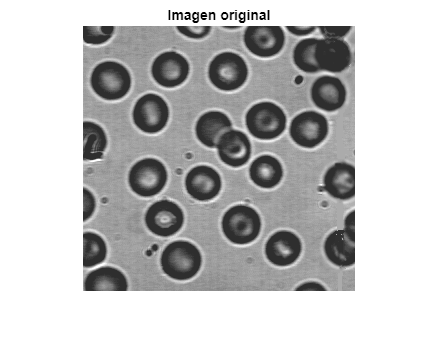

% Cargamos la imagen
I = imread('./imagenes/blood1.tif');

figure, imshow(I); title('Imagen original');

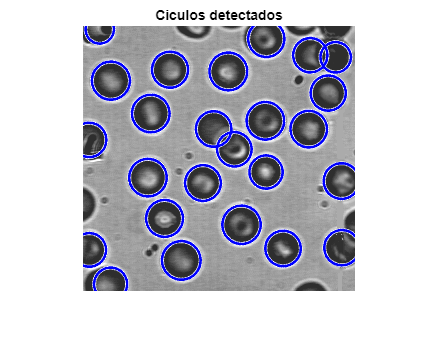

% Limite inferior y superior
Rmin = 7; 
Rmax = 20;

% Detectamos los circulos
[centersBright, radiiBright] = imfindcircles(I,[Rmin Rmax],'ObjectPolarity','dark');

% Mostramos los circulos
figure, imshow(I); title('Ciculos detectados');
viscircles(centersBright, radiiBright,'Color','b');

- Resalte la célula más grande pintándola de un color diferente.

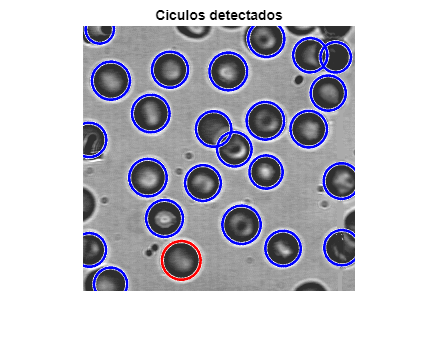

% Obtenemos la celula mas grande
idx = 1;
for i = 2:length(centersBright)
    if radiiBright(i) > radiiBright(idx)
        idx = i;
    end
end

% Mostramos los circulos
figure, imshow(I); title('Ciculos detectados');
viscircles(centersBright, radiiBright,'Color','b');
viscircles(centersBright(idx,:), radiiBright(idx),'Color','r');

- ¿Cuántas células ha encontrado?

% Mostramos cuantas celulas ha encontrado
length(centersBright)

ans = 25

**Comentarios:**

- Se han identificado 25 células.

- Podemos observar cómo, mediante la transformada de Hough, se detecta el contorno de formas circulares, trazando un círculo con el centro en la ubicación del objeto y un radio ajustado al objeto.

**7. Transformada Watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realize una segmentación utilizando la transformada de Watershed. ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen? En caso de que exista, intente reducirla (utilizando, por ejemplo, operadores morfológicos).

imfinfo('./imagenes/circles.png').ColorType

ans = 'grayscale'

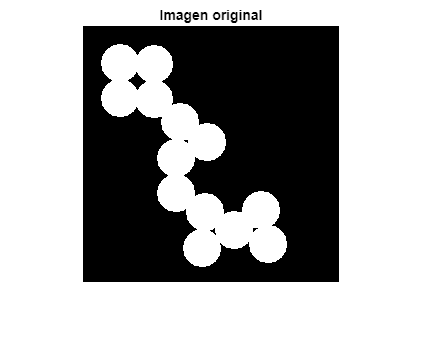

% Cargamos la imagen
I = imread('./imagenes/circles.png');
figure, imshow(I); title('Imagen original');

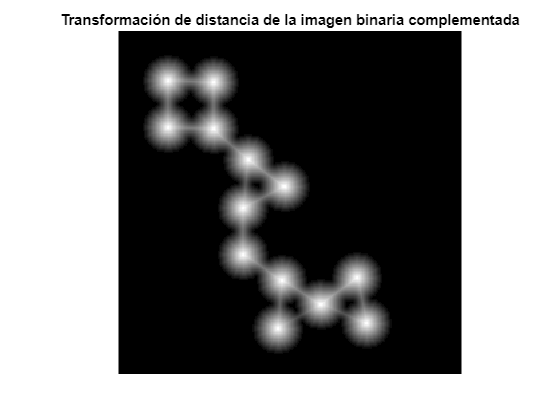

% Se calculan las distancias de los pixeles
nI = ~I;
D = bwdist(nI);

figure,
imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia de la imagen binaria complementada')

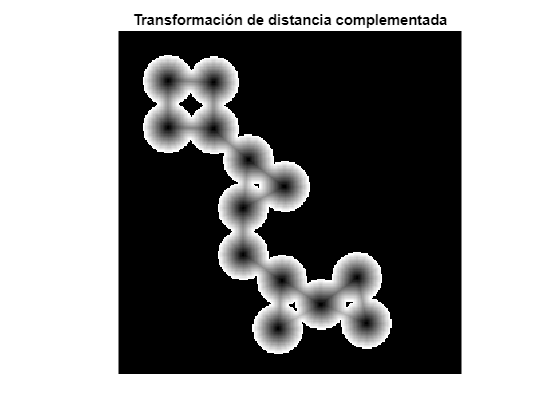

% Se complementa la transformacion de la distancia
D = -D;
D(nI) = -Inf;   

imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia complementada');

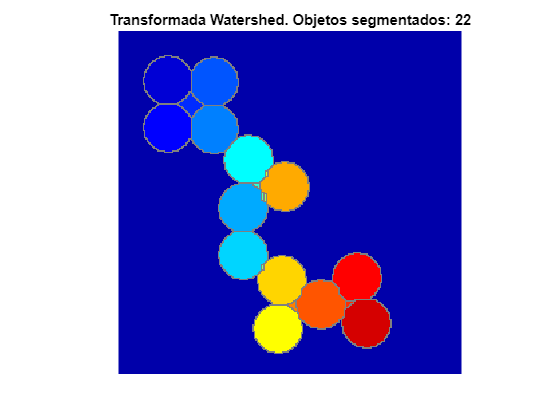

% Se calcula la transformación de Watershed
L = watershed(D);
rgb = label2rgb(L,'jet',[.5 .5 .5]);

figure
imshow(rgb,'InitialMagnification','fit')
title(sprintf('Transformada Watershed. Objetos segmentados: %d',max(max(L,[],1),[],2)));

**Comentarios:**

- Sí, hay sobresegmentación al realizar la transformada de Watershed. Observamos la creación de objetos adicionales entre los círculos que se intentan segmentar. Para corregir esto, aplicaremos operaciones morfológicas con el objetivo de segmentar el número correcto de objetos.

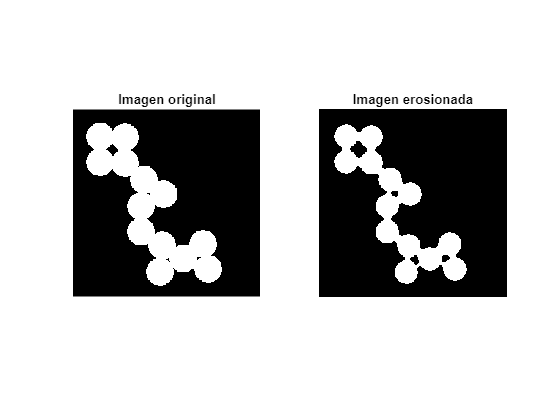

% Realizamos una operacion morfologica
se = strel('disk', 4);
I_close = imerode(I,se); 

figure, 
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(I_close); title('Imagen erosionada');

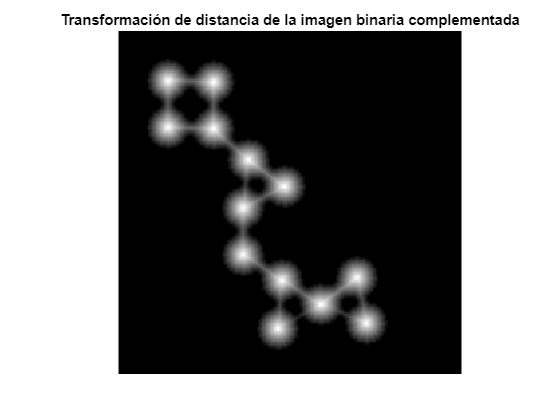

% Se calculan las distancias de los pixeles
nI_close = ~I_close;
D = bwdist(nI_close);

figure
imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia de la imagen binaria complementada')

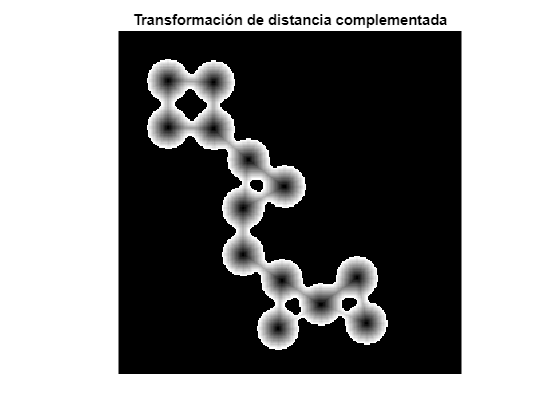

% Se complementa la transformacion de la distancia
D = -D;
D(nI_close) = -Inf;   

imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia complementada');

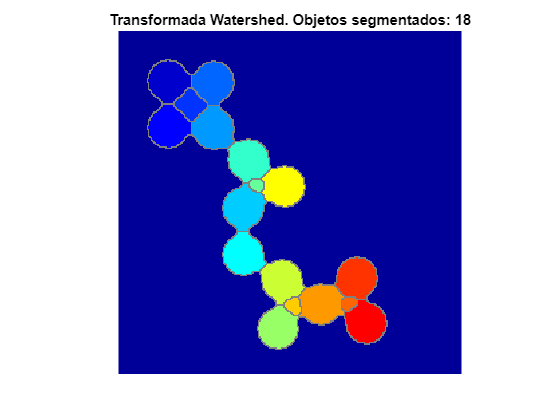

% Se calcula la transformación de Watershed
L = watershed(D);
rgb = label2rgb(L,'jet',[.5 .5 .5]);

figure,
imshow(rgb,'InitialMagnification','fit')
title(sprintf('Transformada Watershed. Objetos segmentados: %d',max(max(L,[],1),[],2)));

**Comentarios:**

- Para determinar el número correcto de objetos, se ha erosionado la imagen de tal manera que los píxeles que se encontraban entre los círculos han reducido su distancia al fondo. Esto evita la generación de nuevos objetos en estos píxeles.

**Opcional.** Umbralización no lineal, para número de clases mayor que 2. En ambos casos se considerará que a la entrada se pueden utilizar imágenes de cualquier tamaño y tipo (indexadas, color y en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar.

**8. **Implemente un programa que realice la segmentación** supervisada** por modelos gaussianos (no lineal) para un número de clases superior a 2. 

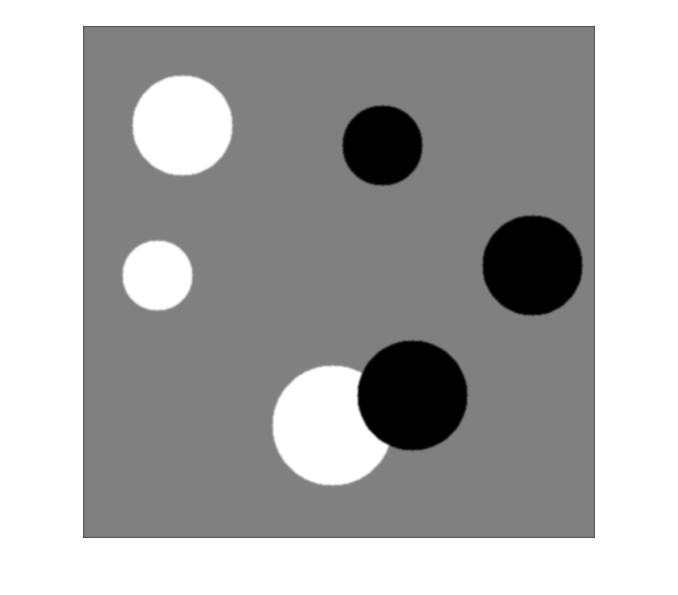

% Ejercicio 8
% Imagen con 3 clases
filename = './imagenes/circlesBrightDark.png';
n_objetos = 3;
I = convertir_imagen(filename);
[media_obj, sd_obj] = calcular_centroides(I, n_objetos);

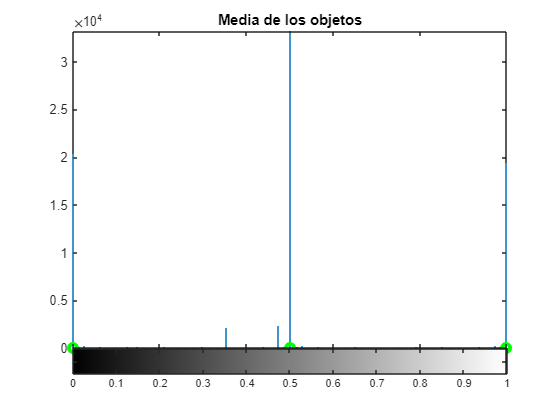

mostrar_centroides(I, n_objetos, media_obj);

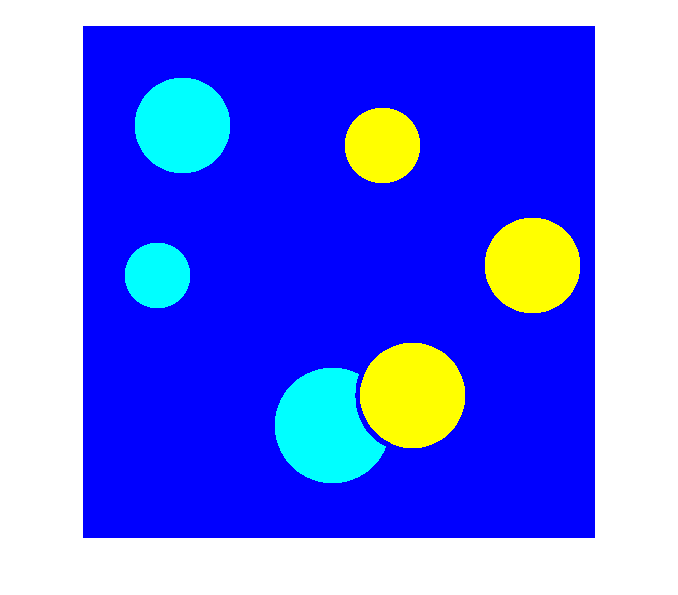

rgb = segmentar(I, n_objetos, media_obj, sd_obj);
figure, imshow(rgb);

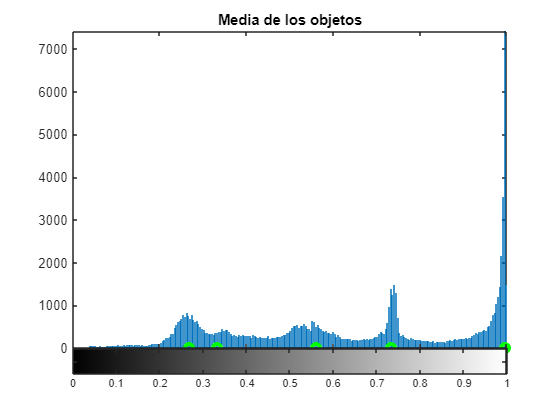

% Imagen con 5 clases
filename = './imagenes/pimientos.jpg';
n_objetos = 5;
I = convertir_imagen(filename);
[media_obj, sd_obj] = calcular_centroides(I, n_objetos);
mostrar_centroides(I, n_objetos, media_obj);

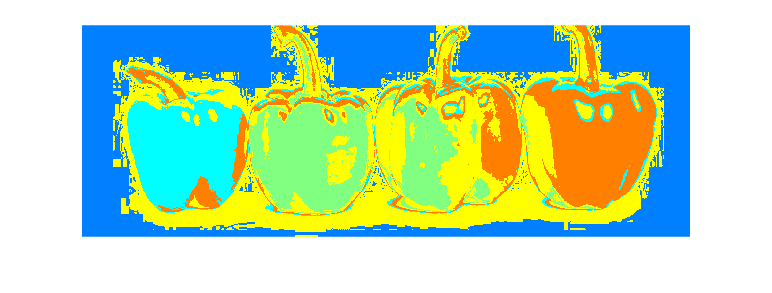

rgb = segmentar(I, n_objetos, media_obj, sd_obj);
figure, imshow(rgb);

**Comentarios:**

- Al aplicar el modelo gaussiano para segmentar las imágenes, podemos observar que la imagen con un histograma que muestra clases claramente separadas se segmenta de manera efectiva. En cambio, la otra imagen, que presenta un histograma más complejo, logra diferenciar algunos objetos, pero no de manera precisa para otros.

**9. **Implemente un programa que realice la segmentación **no supervisada** por modelos gaussianos (no lineal) para un número de clases superior a 2. 

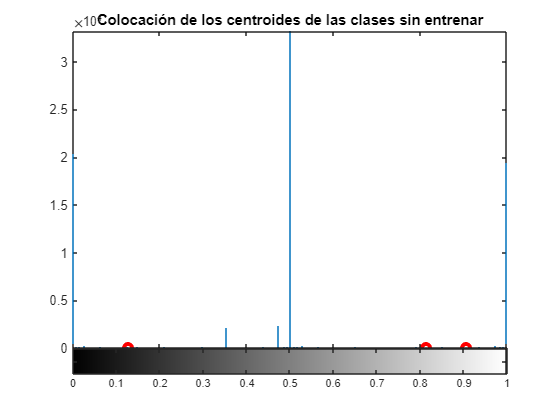

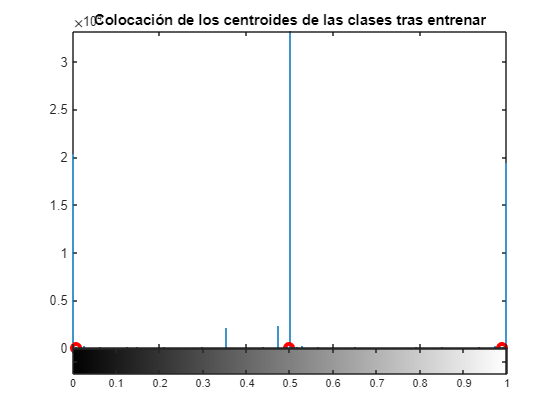

% Imagen con 3 clases
filename = './imagenes/circlesBrightDark.png';
n_objetos = 3;

I = convertir_imagen(filename);
S = colocar_centroides(I, n_objetos);

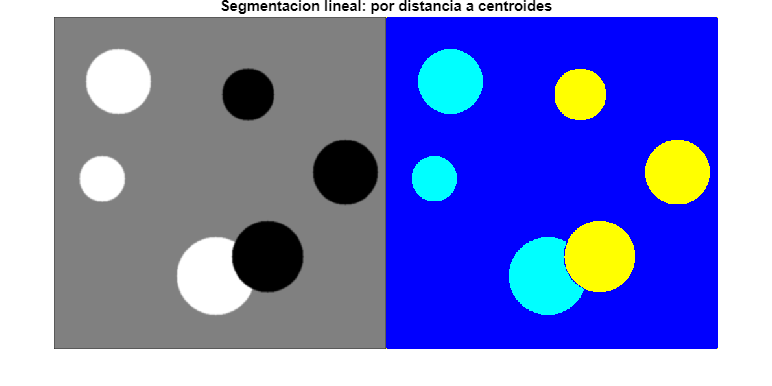

figure,
RGB_S = label2rgb(S); % Convierte la imagen segmentada en una imagen en color usando: label2rgb   
imshowpair(I,RGB_S,'montage')  
title('Segmentacion lineal: por distancia a centroides');

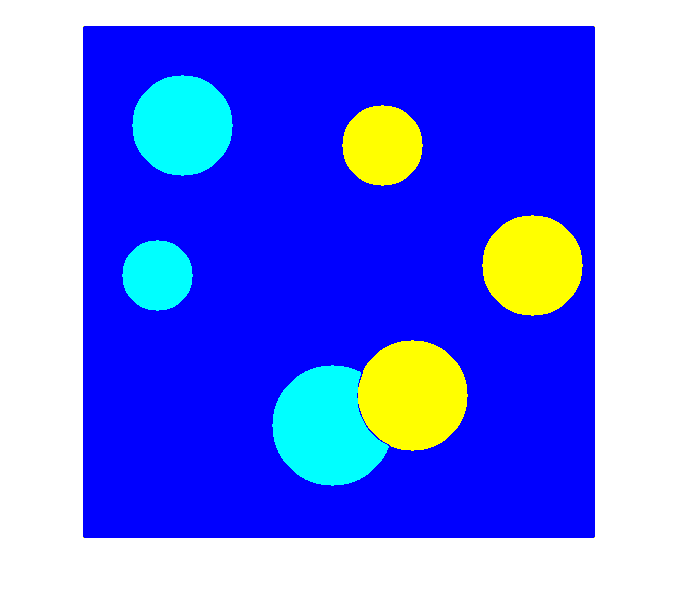

[mclass, sclass] = calcular_datos(I, n_objetos, S);
rgb = segmentar(I, n_objetos, mclass, sclass);

figure, imshow(rgb);

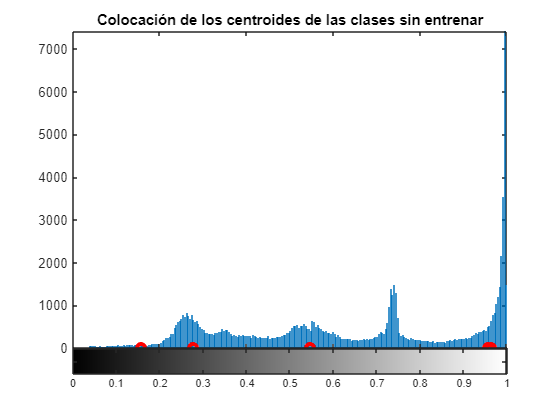

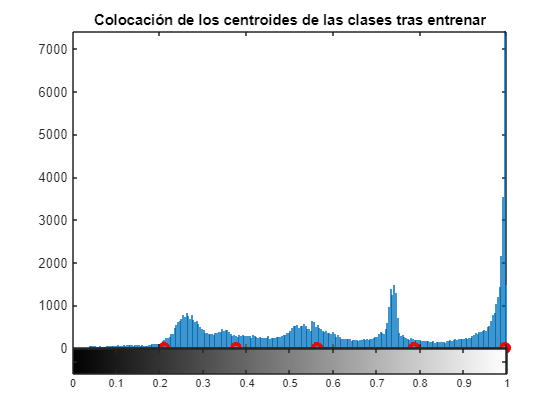

% Imagen con 5 clases
filename = './imagenes/pimientos.jpg';
n_objetos = 5;

I = convertir_imagen(filename);
S = colocar_centroides(I, n_objetos);

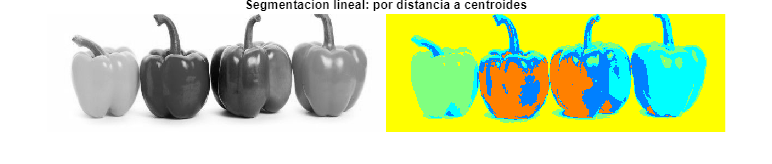

figure,
RGB_S = label2rgb(S); % Convierte la imagen segmentada en una imagen en color usando: label2rgb   
imshowpair(I,RGB_S,'montage')  
title('Segmentacion lineal: por distancia a centroides');

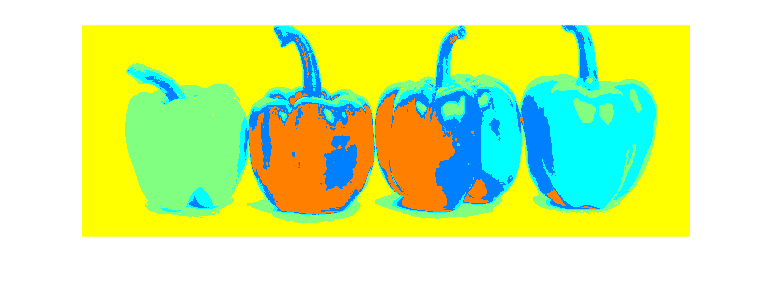

[mclass, sclass] = calcular_datos(I, n_objetos, S);
rgb = segmentar(I, n_objetos, mclass, sclass);

figure, imshow(rgb);

**Comentarios:**

- Aplicando el modelo gaussiano de forma no supervisada, podemos observar que obtenemos un resultado de manera más cómoda, sin la necesidad de seleccionar manualmente los píxeles para la ejecución del algoritmo. Los centroides elegidos al azar se ajustan a la imagen, produciendo un buen resultado. Sin embargo, al aplicar el enfoque de Bayes, se obtiene la imagen final donde se observa que algunos detalles dentro de los objetos han sido corregidos, aunque otros, como las sombras, han aumentado.

% Funciones parte opcional
% Funciones apartados 8 y 9

function [I] = convertir_imagen(filename)
    info = imfinfo(filename);
    
    if strcmp(info.ColorType,'indexed')
        [Y,map] = imread(filename);
        Z = ind2gray(Y,map);
        I=im2double(Z);
    elseif strcmp(info.ColorType,'truecolor')
        rgb=imread(filename);
        Z=rgb2gray(rgb);
        I=im2double(Z);
    elseif  strcmp(info.ColorType,'grayscale')
        I=im2double(imread(filename)); 
    else
        I=imread(filename);
    end
end

function [rgb] = segmentar(I, n_objetos, media_obj, sd_obj)
    [maxX,maxY] = size(I);
    S = zeros(maxX,maxY);
    
    for i = 1:1:maxX 	%Para todas las filas de la imagen
        for j = 1:1:maxY 	%Para todas las columnas de la imagen
            x = I(i,j); %Se toma cada pixel "x" de la imagen
            bayes = zeros(1, n_objetos);
            
            for k = 1:n_objetos
                % se calcula el valor en la función densidad de probabilidad para
                % el valor "x" para cada clase.
                bayes(k) = (1/(sqrt(2*pi)*sd_obj(k))) * exp(-0.5*(x-media_obj(k))'*sd_obj(k)^(-2).*(x-media_obj(k)));  
            end
            
            [~, idx] = max(bayes);
            S(i,j) = idx;
        end
    end
    
    % Pintamos los objetos etiquetados
    rgb = label2rgb(S, 'jet', [.5 .5 .5]);
end

%--------------------------------------------------------------------------------------
% Funciones ejercicio 8
function [media_obj, sd_obj] = calcular_centroides(I, n_objetos)
    pixeles = cell(1, n_objetos);
    % Para cada objeto
    for i = 1:n_objetos
        % Seleccionamos los pixeles del objeto
        fig = figure;
        imshow(I);
        title(sprintf('Selecciona pixeles del objeto %d.', i));
        hold on;
        pixeles{i} = impixel(I);
        close(fig);
    end

    media_obj = zeros(1, n_objetos);
    sd_obj = zeros(1, n_objetos);
    % Para cada objeto
    for i = 1:n_objetos
        % Calculamos la media
        media_obj(i) = mean(pixeles{i}(:,1));
    
        % Calculamos la desviacion
        ds = std(pixeles{i}(:,1)); 
        if (ds == 0) 
            ds = 0.0000001;  
        end
        sd_obj(i) = ds;
    end
end

function mostrar_centroides(I, n_objetos, media_obj)
    % Visualizamos los centroides  
    figure,
    imhist(I);
    hold on,
    for i = 1:n_objetos
        plot(media_obj(i), 0,'go','LineWidth',3); 
    end
    title('Media de los objetos');
    hold off; 
end

%--------------------------------------------------------------------------------------
% Funciones ejercicio 9
function [S] = colocar_centroides(I, conta)
    % Clustering: datos iniciales
    % Numero de clases
    H = imhist(I);
    WW = rand(1,conta); %posicion inicial de los centroides de las clases (neuronas)
    Want = rand(1,conta);
    
    %Visualizacion de la posicion inicial de los centroides
    figure, imhist(I),
    hold on,
    plot(WW,zeros(1,conta),'ro', 'LineWidth',3); 
    title('Colocación de los centroides de las clases sin entrenar');
    hold off; 	
    
    T = 10; %Variable que indica el nº máximo de veces que se repite el bucle
    t = 0; %Variable temporal del bucle	
    error = 1; %Error medio
    alfa_t = 0.15; %Valores para la variable alfa
    
    %Clustering: bucle de entrenamiento para obtener los valores de los centroides que tiendan a ser %las medias de los niveles de gris de las clases
    [maxX,maxY] = size(I);
    T_max = 20; % nº máximo de iteraciones
    error_max = 0.001; % Error maximo permitido
    
    while ((error > error_max) && (t < T_max))   %Entrenamiento de los centroides
        t = t+1;
        for i = 1:5:maxX
            for j = 1:5:maxY
       	        xk = I(i,j);  %Se toma un pixel de muestra "xk" de la imagen
                
                %Se calcula la distancia del pixel "xk" a los centroides de las dos clases
       	        d = dist(xk,WW);
                
       	        [~, ind] = min(d);
                %En "ind" se tiene un "1" o un "2" en funcion de que el pixel "xk" este mas cerca del     
                % centroide de la clase 1 o 2
        	       
                %Se actualiza el centroide de la clase mas cercano a "xk" para que se acerque a la 
                % posicion del pixel "xk"
                WW(ind) = WW(ind) + alfa_t*(xk-WW(ind));
            end
        end
        error = mean(abs(WW - Want));
        Want = WW;
        alfa_t = alfa_t*(1-t/T); %alfa_t disminuye a medida que avanza el numero de iteraciones.
    end   
    
    %Visualizacion de la nueva posicion de los centroides
    figure,imhist(I), hold on,plot(WW,zeros(1,conta),'ro', 'LineWidth',3); 
    title('Colocación de los centroides de las clases tras entrenar');
    hold off; 
    
    S = zeros(maxX,maxY);
    for i = 1:1:maxX
        for j = 1:1:maxY
            xk = I(i,j);   %Se toma un pixel "xk" de la imagen
            d = dist(xk,WW); %Se calcula la distancia del pixel "xk" a los centroides de las dos clases
            [~, ind] = min(d);	 %En "ind" se tiene un "1" o un "2" en funcion de que el pixel "xk" este %mas cerca del centroide de la clase 1 o 2
            S(i,j) = ind; %Es 1 si pertenece a una clase y 2 si pertenece a otra
        end
    end

end

function [mclass, sclass] = calcular_datos(I, n_objetos, S)
    mclass = zeros(1, n_objetos);
    sclass = zeros(1, n_objetos);
    
    for i = 1:n_objetos
        % Media de las clases
        mclass(i) = mean(I(S==i));
    
        % Desviacion tipica de las clases
        s = std(I(S==i));
        if (s==0) 
            s = 0.0000001;  
        end
        sclass(i) = s;
    end
end
